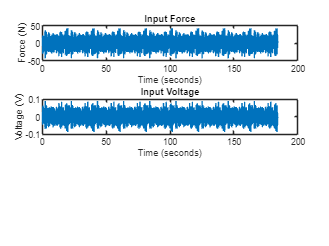

clear;
% Load the data
data = load('F16Data_FullMSine_Level1.mat');

% Extract variables for easier access
Fs = data.Fs; % Sampling frequency
Force = data.Force;
Voltage = data.Voltage;
Acceleration = data.Acceleration; % 3 channels of acceleration data

% Time vector for plotting
time = (0:length(Force)-1) / Fs;

% Plotting the Force and Voltage
figure;
subplot(3,1,1);
plot(time, Force);
title('Input Force');
xlabel('Time (seconds)');
ylabel('Force (N)');

subplot(3,1,2);
plot(time, Voltage);
title('Input Voltage');
xlabel('Time (seconds)');
ylabel('Voltage (V)');

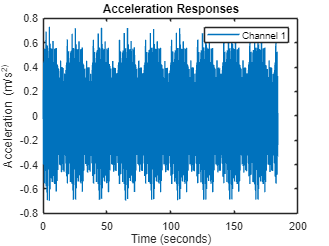


figure;
% Plotting the Acceleration for each channel
plot(time, Acceleration(1,:));
title('Acceleration Responses');
xlabel('Time (seconds)');
ylabel('Acceleration (m/s^2)');
legend('Channel 1');

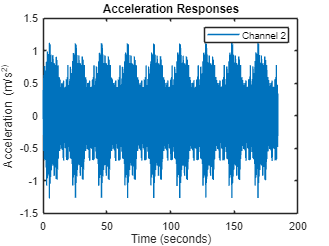


figure;
plot(time, Acceleration(2,:));
title('Acceleration Responses');
xlabel('Time (seconds)');
ylabel('Acceleration (m/s^2)');
legend('Channel 2');

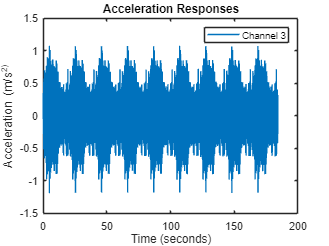


figure;
plot(time, Acceleration(3,:));
title('Acceleration Responses');
xlabel('Time (seconds)');
ylabel('Acceleration (m/s^2)');
legend('Channel 3');

# `Basic Statistical Analysis`

% Basic statistics for Force
force_mean = mean(Force);
force_std = std(Force);

% >> >> >> >> >> Voltage
voltage_mean = mean(Voltage);
voltage_std = std(Voltage);

% >> >> >> >> >>  for each channel of Acceleration
acc_means = mean(Acceleration, 2); % Mean across rows
acc_stds = std(Acceleration, 0, 2); % Standard deviation across rows

% Display results
disp(['Force Mean: ', num2str(force_mean), ', Standard Deviation: ', num2str(force_std)]);

Force Mean: 1.1908e-05, Standard Deviation: 12.365


disp(['Voltage Mean: ', num2str(voltage_mean), ', Standard Deviation: ', num2str(voltage_std)]);

Voltage Mean: 2.3783e-08, Standard Deviation: 0.025029


disp(['Acceleration Means: ', num2str(acc_means')]);

Acceleration Means: 2.8021e-06 -8.0648e-06 -1.3127e-05


disp(['Acceleration Standard Deviations: ', num2str(acc_stds')]);

Acceleration Standard Deviations: 0.24366     0.38699     0.35959


# `Frequency Analysis of the acceleration data`

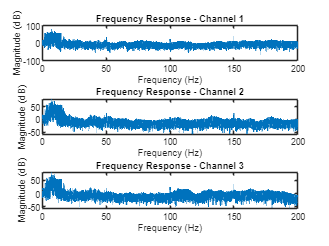

% Perform FFT on the acceleration data
N = size(Acceleration, 2);
frequencies = (0:N-1)*(Fs/N);
Y = fft(Acceleration, [], 2); % FFT along each row

% Plot the magnitude spectrum
figure;
for i = 1:3
    subplot(3,1,i);
    plot(frequencies, db(abs(Y(i,:))), 'LineWidth', 1.5);
    xlim([0 Fs/2]); % Plot up to Nyquist frequency
    title(['Frequency Response - Channel ', num2str(i)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
end

# `Correlation between input forces/voltage and output accelerations`

% correlation coefficients
corr_force_acc = corr(Force', Acceleration');
corr_voltage_acc = corr(Voltage', Acceleration');

disp(['Correlation between Force and Accelerations: ', num2str(corr_force_acc)]);

Correlation between Force and Accelerations: 0.70393     0.32008     0.28573


disp(['Correlation between Voltage and Accelerations: ', num2str(corr_voltage_acc)]);

Correlation between Voltage and Accelerations: -0.6318    -0.23825    -0.20229


# `Model Implementation`

% Normalize data (optional based on previous analyses)
Force_norm = (Force - mean(Force)) / std(Force);
Voltage_norm = (Voltage - mean(Voltage)) / std(Voltage);
Acceleration_norm = bsxfun(@minus, Acceleration, mean(Acceleration, 2)) ./ std(Acceleration, 0, 2);

% Prepare inputs and outputs
inputs = [Force_norm; Voltage_norm]';
outputs = Acceleration_norm'; % Using the first channel as an example

% Split data into training and validation sets
num_samples = length(outputs);
idx = randperm(num_samples);
train_idx = idx(1:floor(0.8*num_samples));
test_idx = idx(floor(0.8*num_samples)+1:end);

X_train = inputs(train_idx, :);
Y_train = outputs(train_idx, 1); % Training on the first acceleration channel
X_test = inputs(test_idx, :);
Y_test = outputs(test_idx, 1);



% Linear Model
lin_model = LinRegress(X_train, Y_train);

% Polynomial Model - degree 3 with regularization
lambda = 0.01; % Regularization parameter
degree = 3; % Degree of the polynomial
poly_model = polyfit(X_train, Y_train, lambda, degree);



% Evaluate Linear Model
Y_pred_lin = evalModel(lin_model, X_test);
rmse_lin = sqrt(mean((Y_test - Y_pred_lin).^2));
disp(['RMSE for Linear Model: ', num2str(rmse_lin)]);

RMSE for Linear Model: 0.46393



% Evaluate Polynomial Model
Y_pred_poly = evalModel(poly_model, X_test);
rmse_poly = sqrt(mean((Y_test - Y_pred_poly).^2));
disp(['RMSE for Polynomial Model: ', num2str(rmse_poly)]);

RMSE for Polynomial Model: 0.46244


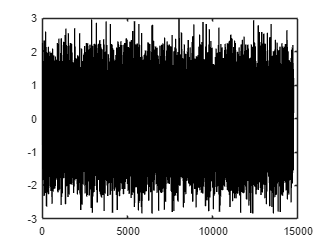



figure;
plot(Y_test, 'k-', 'DisplayName', 'Actual Data');
hold on;

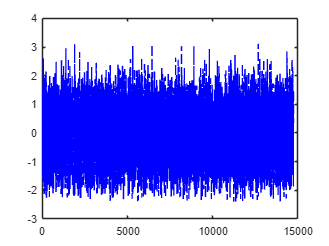

figure;
plot(Y_pred_lin, 'b--', 'DisplayName', 'Linear Model Predictions');
hold on;

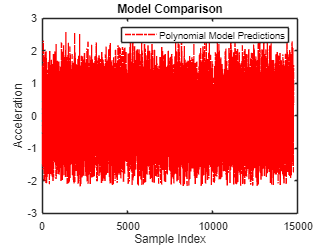


figure;
plot(Y_pred_poly, 'r-.', 'DisplayName', 'Polynomial Model Predictions');
legend show;
xlabel('Sample Index');
ylabel('Acceleration');
title('Model Comparison');